# Exercises

Exercises were completed with the help of ChatGPT, link to conversation can be found here

Using the following data set to investigate the relationship between Age and Wing Length, and use the data to generate answers to the prompts below: 

**Age - Wing Length**

3 - 1.4

4 - 1.5

5 - 2.2

6 - 2.4

7 - 3.1

8 - 3.2

9 - 3.2

11 - 3.9

12 - 4.1

14 - 4.7

15 - 4.5

16 - 5.2

17 - 5.0

1. Plot the relationship between Age and Wing Length.

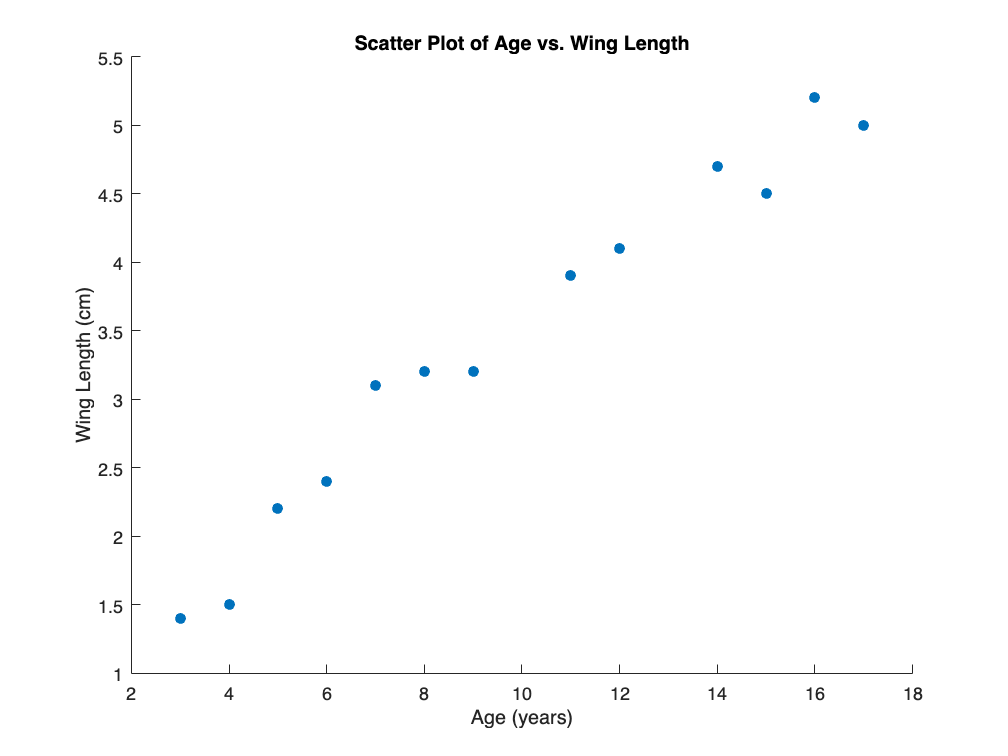

% Define age and wing length
age = [3,4,5,6,7,8,9,11,12,14,15,16,17];
wing_length = [1.4, 1.5, 2.2, 2.4, 3.1, 3.2, 3.2, 3.9, 4.1, 4.7, 4.5, 5.2, 5.0];

% Create a scatter plot
scatter(age, wing_length, 'filled');

% Add labels and title
xlabel('Age (years)');
ylabel('Wing Length (cm)');
title('Scatter Plot of Age vs. Wing Length');


% Display the plot

2. Calculate and plot the regression line.

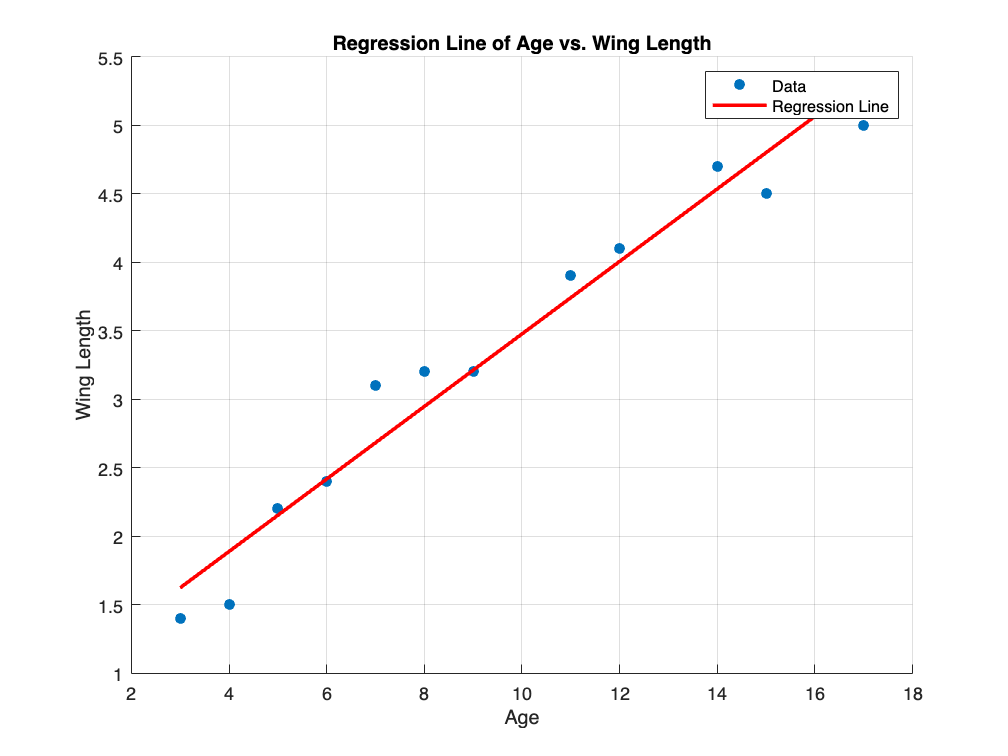

% Perform linear regression
coefficients = polyfit(age, wing_length, 1);

% Create a scatter plot
scatter(age, wing_length, 'filled'); % 'filled' adds markers to the points
hold on;

% Calculate the regression line
x_fit = linspace(min(age), max(age), 100);
y_fit = polyval(coefficients, x_fit);

% Plot the regression line
plot(x_fit, y_fit, 'r', 'LineWidth', 2);

% Label the axes
xlabel('Age');
ylabel('Wing Length');

% Add a title
title('Regression Line of Age vs. Wing Length');

% Show the legend
legend({'Data', 'Regression Line'});

% Show the grid
grid on;

% Release the hold on the plot
hold off;

3. Can you reject H_0: b=0?

- Probably not, given that there is a clear positive slope for the regression line plotted over our data. This suggests that there is at least a weak ppositive correlation present in our sample. 

4. Calculate and plot the confidence intervals on the slope of the regression.

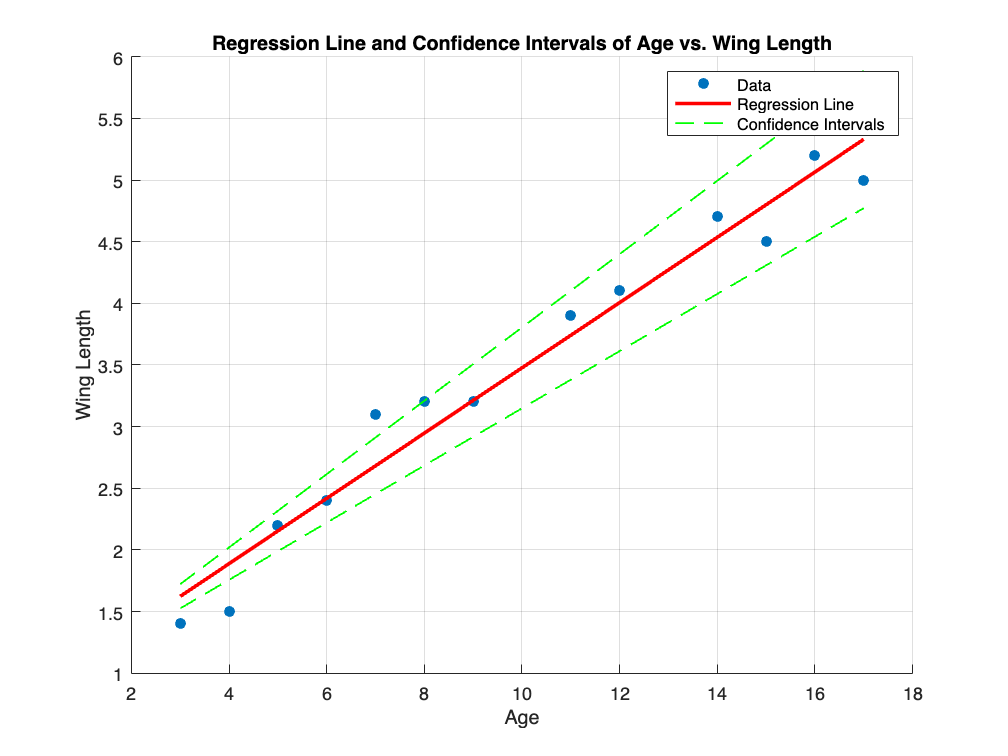

% Extract the slope and intercept
slope = coefficients(1);
intercept = coefficients(2);

% Calculate the standard error of the slope
residuals = wing_length - polyval(coefficients, age);
residual_std = std(residuals);
n = length(age);
std_error_slope = residual_std / sqrt(sum((age - mean(age)).^2));

% Set the confidence level (e.g., 95% confidence interval)
alpha = 0.05;

% Calculate the critical t-value for the given alpha and degrees of freedom
df = n - 2; % degrees of freedom
t_critical = tinv(1 - alpha / 2, df);

% Calculate the margin of error
margin_error = t_critical * std_error_slope;

% Calculate the confidence interval for the slope
slope_lower = slope - margin_error;
slope_upper = slope + margin_error;

% Create a scatter plot
scatter(age, wing_length, 'filled'); % 'filled' adds markers to the points
hold on;

% Calculate the regression line
x_fit = linspace(min(age), max(age), 100);
y_fit = polyval(coefficients, x_fit);

% Plot the regression line
plot(x_fit, y_fit, 'r', 'LineWidth', 2);

% Plot the confidence intervals
plot(x_fit, polyval([slope_lower, intercept], x_fit), '--g', 'LineWidth', 1);
plot(x_fit, polyval([slope_upper, intercept], x_fit), '--g', 'LineWidth', 1);

% Label the axes
xlabel('Age');
ylabel('Wing Length');

% Add a title
title('Regression Line and Confidence Intervals of Age vs. Wing Length');

% Show the legend
legend({'Data', 'Regression Line', 'Confidence Intervals'});

% Show the grid
grid on;

% Release the hold on the plot
hold off;


% Display the confidence interval values
fprintf('95%% Confidence Interval for Slope: (%.4f, %.4f)\n', slope_lower, slope_upper);

95% Confidence Interval for Slope: (0.2319, 0.2975)


5. Calculate r^2 (the coefficient of determination)

% Calculate the predicted values
y_pred = polyval(coefficients, age);

% Calculate the total sum of squares (TSS)
TSS = sum((wing_length - mean(wing_length)).^2);

% Calculate the residual sum of squares (RSS)
RSS = sum((wing_length - y_pred).^2);

% Calculate R-squared
R_squared = 1 - (RSS / TSS);

fprintf('R-squared value: %.4f\n', R_squared);

R-squared value: 0.9634


6. Calculate Pearson's *r*.

% Calculate Pearson's r value
r = corrcoef(age, wing_length);
r = r(1, 2); % Extract the correlation coefficient from the matrix

fprintf('Pearson''s r value: %.4f\n', r);

Pearson's r value: 0.9815


7. Add some noise to the data and see how the regression changes.

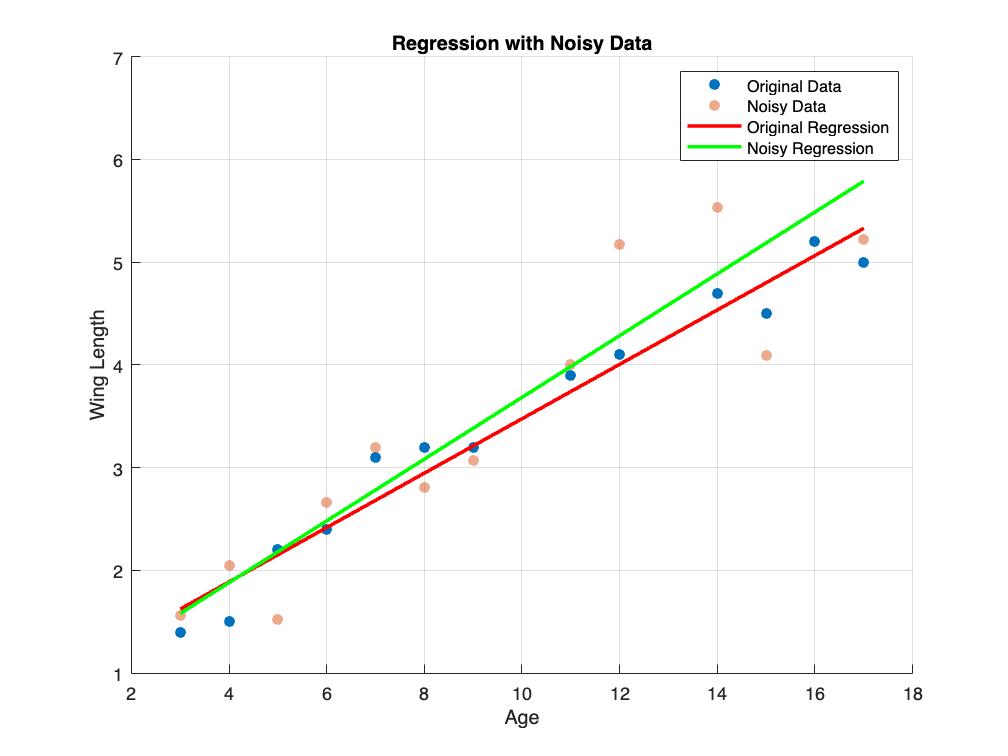

% Add some random noise
rng(0); % Set seed for reproducibility
noise = normrnd(0, 0.3, size(wing_length)); % Generate random noise with mean 0 and standard deviation 0.3
noisy_wing_length = wing_length + noise;

% Perform linear regression on the noisy data
coefficients_noisy = polyfit(age, noisy_wing_length, 1);

% Calculate the predicted values
y_pred_noisy = polyval(coefficients_noisy, age);

% Calculate R-squared for the noisy data
TSS_noisy = sum((noisy_wing_length - mean(noisy_wing_length)).^2);
RSS_noisy = sum((noisy_wing_length - y_pred_noisy).^2);
R_squared_noisy = 1 - (RSS_noisy / TSS_noisy);

% Plot the original and noisy data along with regression lines
figure;
scatter(age, wing_length, 'filled'); % Original data
hold on;
scatter(age, noisy_wing_length, 'filled', 'MarkerFaceAlpha', 0.5); % Noisy data
x_fit = linspace(min(age), max(age), 100);
y_fit_original = polyval(coefficients, x_fit);
y_fit_noisy = polyval(coefficients_noisy, x_fit);
plot(x_fit, y_fit_original, 'r', 'LineWidth', 2); % Original regression line
plot(x_fit, y_fit_noisy, 'g', 'LineWidth', 2); % Noisy regression line

% Label the axes
xlabel('Age');
ylabel('Wing Length');

% Add a title
title('Regression with Noisy Data');

% Show the legend
legend({'Original Data', 'Noisy Data', 'Original Regression', 'Noisy Regression'});

% Show the grid
grid on;


% Display R-squared values
fprintf('Original R-squared value: %.4f\n', R_squared);

Original R-squared value: 0.9634


fprintf('Noisy R-squared value: %.4f\n', R_squared_noisy);

Noisy R-squared value: 0.8607
